# Class: Wireless Communications, Prof. Sundeep Ragan

# Student: Jaime Lima, jdl679, N17822573 

# Project: A Short Qualtivative and Quantitative Investigation on NR Phase Noise Modeling, ICI and CPE 

This example demonstrates the impact of phase noise in a 5G OFDM system and shows how to use phase tracking reference signal (PT-RS) in compensating the common phase error (CPE). The example measures error vector magnitude (EVM) and bit error rate (BER) with and without CPE compensation.

## **Introduction**

In 5G NR, 3GPP introduces a new reference signal, named phase tracking reference signal (PT-RS), to deal with oscillator noise. The noise incurred in the oscillators results in phase modulation of the information signal, leading to significant changes in the frequency spectrum and timing properties of the information signal. This phenomenon related to oscillators is called phase noise. Phase noise produced in local oscillators introduces a significant degradation at millimeter wave (mmWave) frequencies, depending on the power spectral density of phase noise. Phase noise leads to CPE and intercarrier interference (ICI). **CPE leads** to an identical rotation of a received symbol in each subcarrier. **ICI leads** to a loss of orthogonality between the subcarriers. Due to the distributed structure of PT-RS in frequency domain, the example primarily uses PT-RS to estimate and minimize the effect of CPE on system performance. The example applies phase noise on the waveform consisting of physical downlink shared channel (PDSCH) and shows the change in EVM and BER without and with CPE compensation. This figure shows the processing chain implemented in this example.

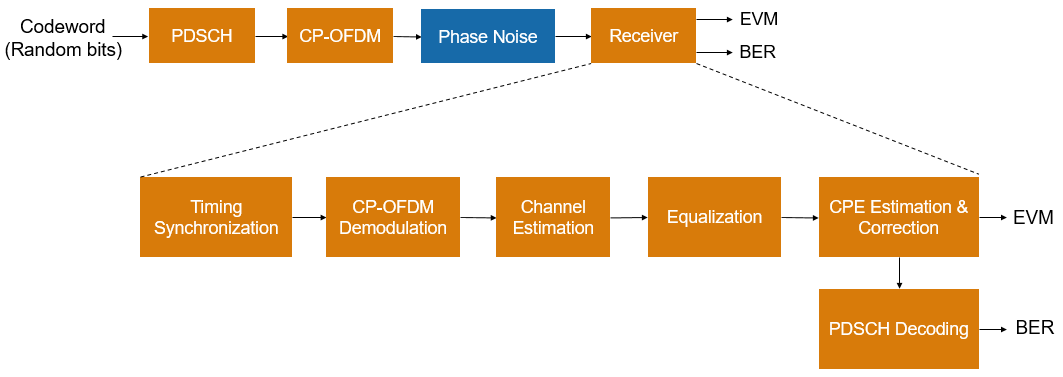

## 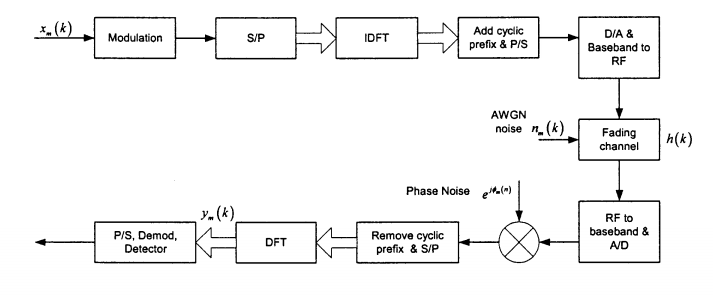

                                   Model of wireless system inclusing phase noise (picture taken from (1))

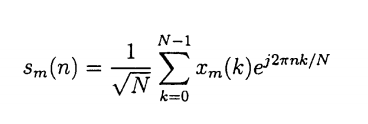

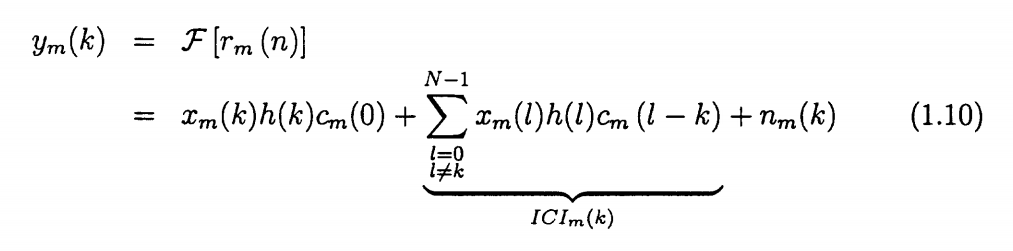

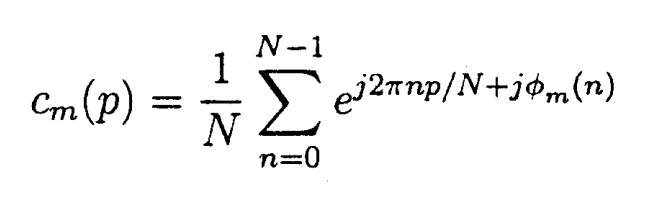

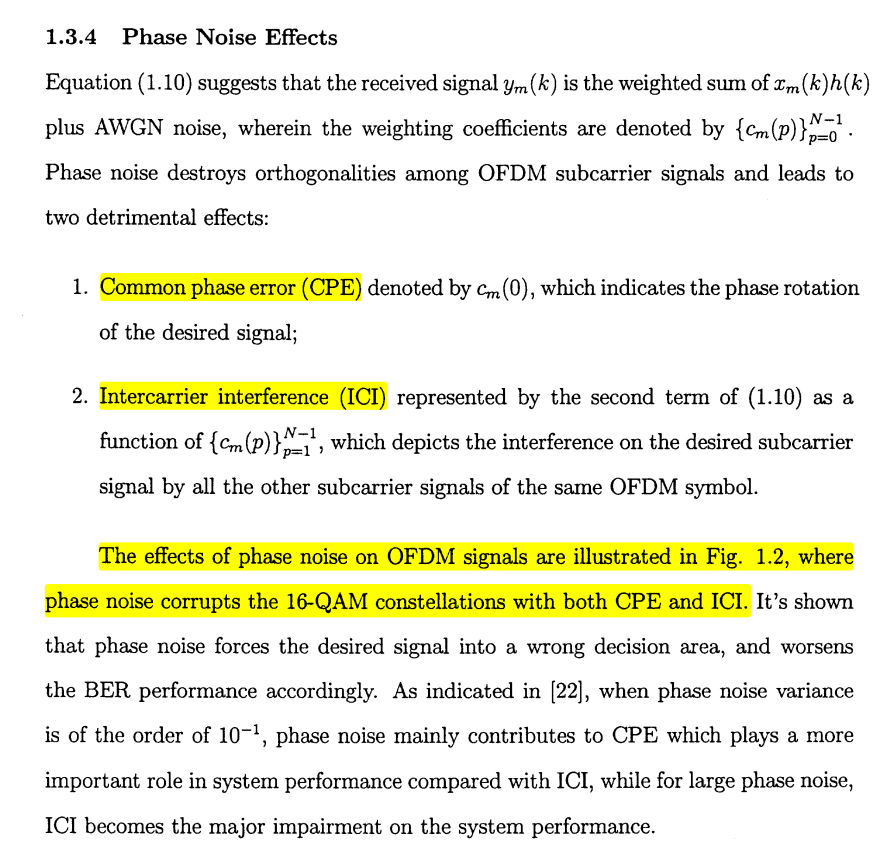

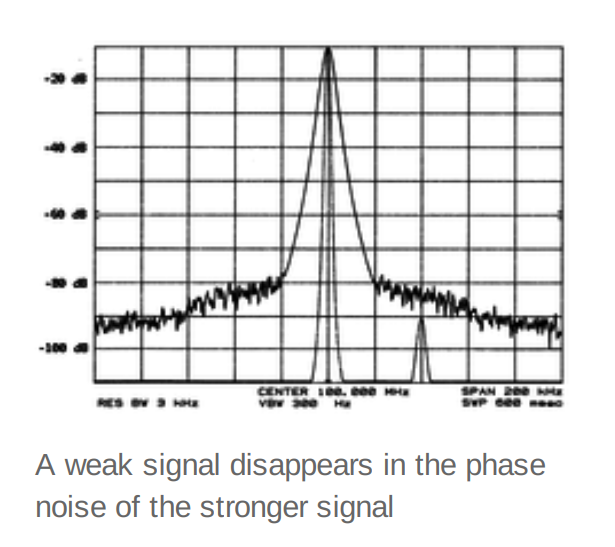

## **Phase Noise Modeling**

**The oscillator power spectral density models the phase noise.** This example uses a multipole zero model to approximate the power spectral density of the oscillator. Use the `PNModel` field of the `simParameters` structure to select the phase noise model: 'A', 'B', or 'C'. Parameter sets 'A' and 'B' are obtained from practical oscillators operating at 30 GHz and 60 GHz, respectively, as described in TDoc R1-163984. The parameter set 'C' is obtained from the practical oscillator operating at 29.55 GHz, as described in TR 38.803 Section 6.1.10.

The example uses a carrier with a subcarrier spacing of 60 kHz for a transmission bandwidth of 50 MHz.

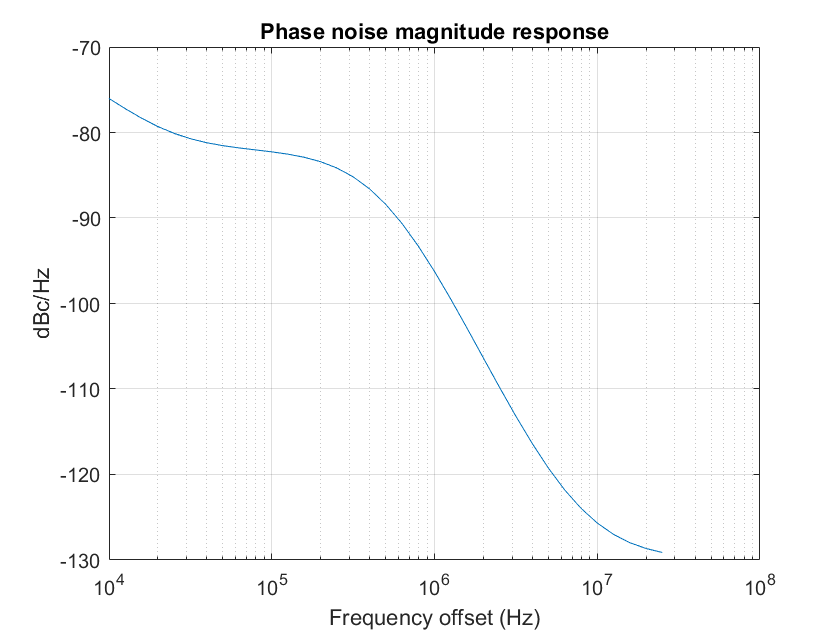

clear all
% Configure carrier
carrier                   = nrCarrierConfig;
carrier.SubcarrierSpacing = 60/1; % KHz
carrier.CyclicPrefix      = 'normal';
carrier.NSizeGrid         = 66/1;

% Set the operating frequency and choose the phase noise model
simParameters         = [];
% simParameters.Fc      = 30e9; % Frequency in Hz
% simParameters.PNModel = 'A'; % 'A' (TDoc R1-163984 Set A), 'B' (TDoc R1-163984 Set B), 'C' (TR 38.803)
simParameters.Fc      = 60e9; % Frequency in Hz
simParameters.PNModel = 'B'; % 'A' (TDoc R1-163984 Set A), 'B' (TDoc R1-163984 Set B), 'C' (TR 38.803)
% simParameters.Fc      = 29.55e9; % Frequency in Hz
% simParameters.PNModel = 'C'; % 'A' (TDoc R1-163984 Set A), 'B' (TDoc R1-163984 Set B), 'C' (TR 38.803)

% Get the sample rate
waveformConfig = nrOFDMInfo(carrier);
sr             = waveformConfig.SampleRate;

% Phase noise level
foffsetLog = (4:0.1:log10(sr/2)); % Model offset from 1e4 Hz to sr/2 Hz
foffset = 10.^foffsetLog;         % Linear frequency offset
% pn_PSD = hPhaseNoisePoleZeroModel(foffset,simParameters.Fc,simParameters.PNModel); % dBc/Hz
pn_PSD = PN_Model2Use(foffset,simParameters.Fc, simParameters.PNModel);  % dBc/Hz

% Set phase noise level
pnoise = comm.PhaseNoise('FrequencyOffset',foffset,'Level',pn_PSD,'SampleRate',sr);
pnoise.RandomStream = "mt19937ar with seed";

% Visualize spectrum mask of phase noise
figure 
semilogx(foffset,pn_PSD)
xlabel('Frequency offset (Hz)')
ylabel('dBc/Hz')
title('Phase noise magnitude response')
grid on

## **Configure PDSCH**

The example configures PDSCH occupying the complete carrier with modulation scheme set to '64QAM' and number of layers set to 1. The example defaults to a single layer and a single codeword of random uncoded bits.

% Set PDSCH parameters
pdsch = nrPDSCHConfig;
pdsch.PRBSet = 0:carrier.NSizeGrid-1;
pdsch.SymbolAllocation = [0 14];
pdsch.Modulation = '64QAM';
pdsch.NumLayers = 1;
pdsch.MappingType = 'A';
pdsch.NID = 1;
pdsch.RNTI = 2;

% Set DM-RS parameters
pdsch.DMRS.DMRSConfigurationType = 1;
pdsch.DMRS.DMRSTypeAPosition = 2;
pdsch.DMRS.DMRSAdditionalPosition = 0;
pdsch.DMRS.DMRSLength = 1;
pdsch.DMRS.DMRSPortSet = [];
pdsch.DMRS.NumCDMGroupsWithoutData = 1;
pdsch.DMRS.NIDNSCID = 1;
pdsch.DMRS.NSCID = 0;

% Set PT-RS parameters
pdsch.EnablePTRS = 1;
pdsch.PTRS.TimeDensity = 1;
pdsch.PTRS.FrequencyDensity = 2;
pdsch.PTRS.REOffset = '00';
pdsch.PTRS.PTRSPortSet = [];

## **Generate Waveform**

The waveform is generated for 2 frames and the field `NumFrames` of `simParameters` structure controls the number of frames of the waveform. The steps involved are:

- Generate random codeword with the bit capacity of PDSCH

- Get the PDSCH symbols for the random codeword and map them to grid

- Generate and map DM-RS symbols to grid

- Generate and map PT-RS symbols to grid

- Perform OFDM modulation for the complete grid of all frames

% Number of frames to generate the waveform
simParameters.NumFrames = 2;

% Get the number of slots in the waveform and number of symbols in a slot
numSlots = carrier.SlotsPerFrame*simParameters.NumFrames;
nSlotSymb = carrier.SymbolsPerSlot;

% Initialize the grid for specified number of frames
txGrid = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);
txGrid_nodata = txGrid;

% Processing loop
txbits = [];
rng('default')
for slotIdx = 0:numSlots - 1
    % Set slot number
    carrier.NSlot = slotIdx;

    % Get PDSCH indices and structural information
    [pdschInd,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);

    % Generate random codeword(s)
    numCW = pdsch.NumCodewords; % Number of codewords
    data = cell(1,numCW);
    for i = 1:numCW
        data{i} = randi([0 1],pdschIndicesInfo.G(i),1);
%         data{i} = zeros(pdschIndicesInfo.G(i),1);
%         data{i} = 0*randi([0 1],pdschIndicesInfo.G(i),1);
        txbits = [txbits; data{i}]; %#ok<AGROW>
    end

    % Get modulated symbols
    pdschSym = nrPDSCH(carrier,pdsch,data);

    % Get DM-RS symbols and indices
    dmrsSym = nrPDSCHDMRS       (carrier,pdsch);
    dmrsInd = nrPDSCHDMRSIndices(carrier,pdsch);

    % Get PT-RS symbols and indices
    ptrsSym = nrPDSCHPTRS(carrier,pdsch);
    ptrsInd = nrPDSCHPTRSIndices(carrier,pdsch);

    % Resource element mapping to slot grid
    slotGrid = nrResourceGrid(carrier,pdsch.NumLayers);
    slotGrid(dmrsInd)  = dmrsSym;
    slotGrid(ptrsInd)  = ptrsSym;
% REMEMBER: y2 = wgn(numSamples,1,pow2db(noiseVar),'complex');
%     slotGrid(dmrsInd)  = sqrt(0.5)*(randn(size(dmrsSym))+1i*randn(size(dmrsSym))) .*dmrsSym;
%     slotGrid(ptrsInd)  = sqrt(0.5)*(randn(size(ptrsSym))+1i*randn(size(ptrsSym))) .*ptrsSym;
%     slotGrid(dmrsInd)  = sqrt(0.5)*(rand (size(dmrsSym))+1i*rand (size(dmrsSym))) .*dmrsSym;
%     slotGrid(ptrsInd)  = sqrt(0.5)*(rand (size(ptrsSym))+1i*rand (size(ptrsSym))) .*ptrsSym;
    slotGrid_nodata = slotGrid;
    slotGrid(pdschInd) = pdschSym;

    % Generate txGrid for all frames by mapping slotGrid at respective
    % locations
    txGrid(:,slotIdx*nSlotSymb+1:(slotIdx+1)*(nSlotSymb),:) = slotGrid;
    txGrid_nodata(:,slotIdx*nSlotSymb+1:(slotIdx+1)*(nSlotSymb),:) = slotGrid_nodata;
end

% figure(); clf; imagesc(abs(txGrid(1:10,end-14+1:end))); colorbar();

CRANGE=[0,0.10];
% figure();clf;imagesc(abs(slotGrid_nodata(1:10,end-14+1:end)),CRANGE); colorbar();
% figure(); clf; imagesc(abs(slotGrid_nodata(:,end-14+1:end)), CRANGE); colorbar();


% Perform OFDM modulation
carrier.NSlot = 0; % Reset the slot number to 0 for OFDM modulation
txWaveform        = nrOFDMModulate(carrier,txGrid);
txWaveform_nodata = nrOFDMModulate(carrier,txGrid_nodata);
% aux = mag2db(abs(fftshift(fft(txWaveform_nodata)))+eps);
% figure();clf;plot(aux); ylim([-40,50])

% aux = mag2db(abs(fftshift(fft(txWaveform_nodata)))+eps);
% figure();clf;plot(aux); ylim([-40,50])


## **Apply Phase Noise**

Apply phase noise to the transmitted waveform. To clearly observe the impact of phase noise, the example does not apply any thermal noise or channel model in addition to phase noise. The example applies the same phase noise to all the layers.

% Apply PN to the frames populated with data
rxWaveform = zeros(size(txWaveform),'like',txWaveform);
for i = 1:size(txWaveform,2)
    rxWaveform(:,i) = pnoise(txWaveform(:,i));
    release(pnoise)
end

% Apply PN to the frames populated DM-RS PT-RS control signals only
rxWaveform_nodata = zeros(size(txWaveform_nodata),'like',txWaveform_nodata);
for i = 1:size(txWaveform_nodata,2)
    rxWaveform_nodata(:,i) = pnoise(txWaveform_nodata(:,i));
    release(pnoise)
end


## **Receiver 1 - A Simple Receiver to observe the Intercarrier Interference (ICI)**

Because the example does not use a propagation channel, the steps of timing synchronization, channel estimation, and equalization are not necessary for this case. The only effect to observe are the ones from the insertion of phase noise.

In this section we will show evidenc of ICI due to phase noise. Later we will show the CPE and ways to mitigate the CPE. I full descrition of the topic can be found in the reference 1.

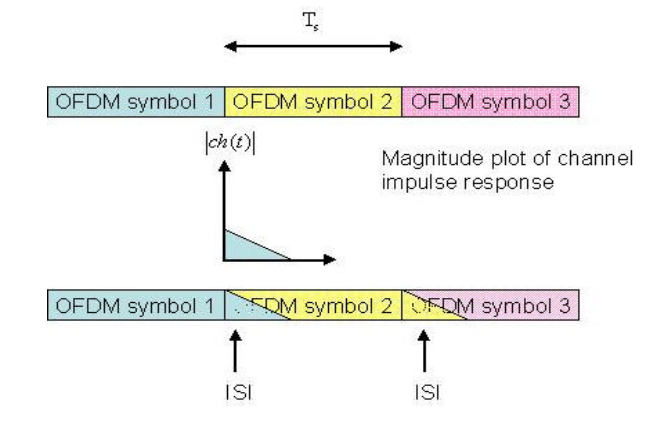

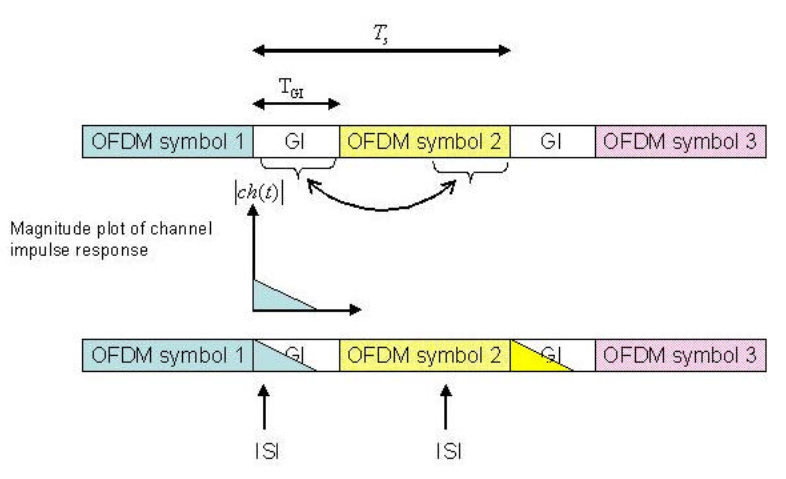

Picture taken from (4), pages 14 and 15

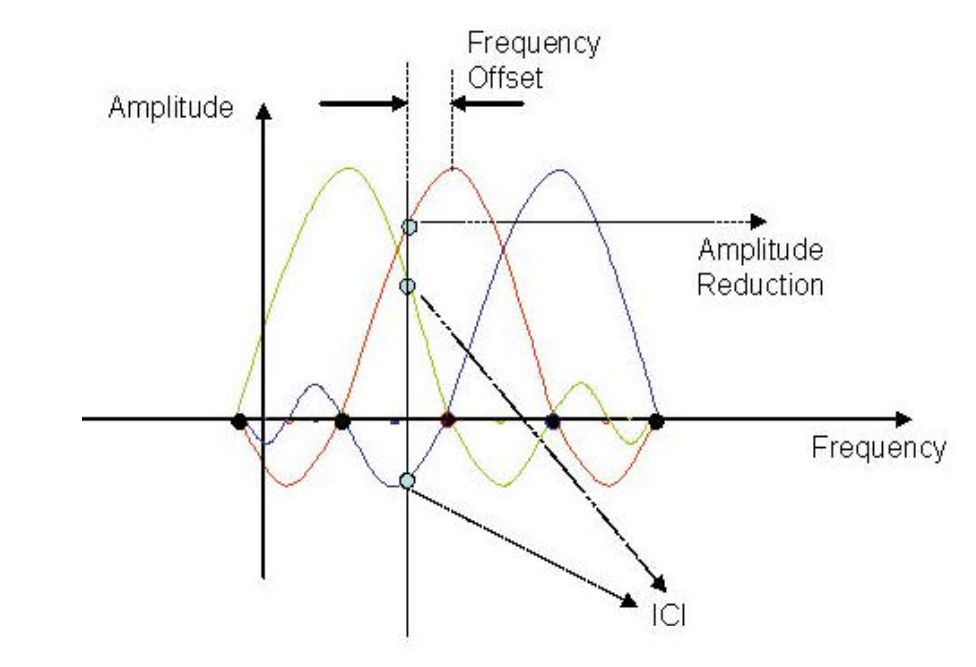

Picture taken from (4), page 25

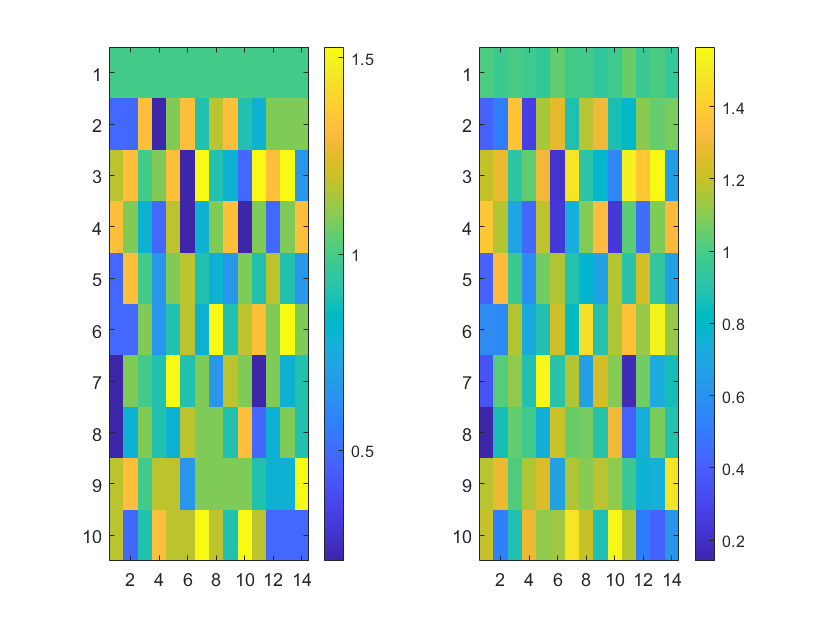


% simParameters.CompensateCPE = 0;
rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
% rxGrid = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
figure(); clf; 
subplot(1,2,1);imagesc(abs(txGrid(1:10,end-14+1:end))); colorbar();
subplot(1,2,2);imagesc(abs(rxGrid(1:10,end-14+1:end))); colorbar();

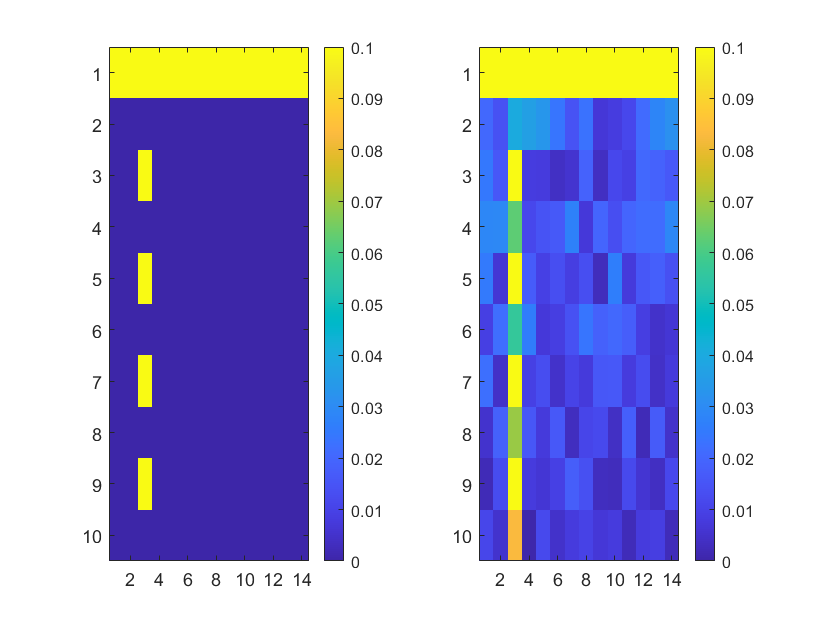


rxGrid_nodata = nrOFDMDemodulate(carrier,rxWaveform_nodata);
% rxGrid_nodata = practicalReceiver(carrier,pdsch,simParameters,rxWaveform_nodata);
figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(1:10,end-14+1:end)),CRANGE); colorbar();
subplot(1,2,2); imagesc(abs(rxGrid_nodata  (1:10,end-14+1:end)),CRANGE); colorbar();

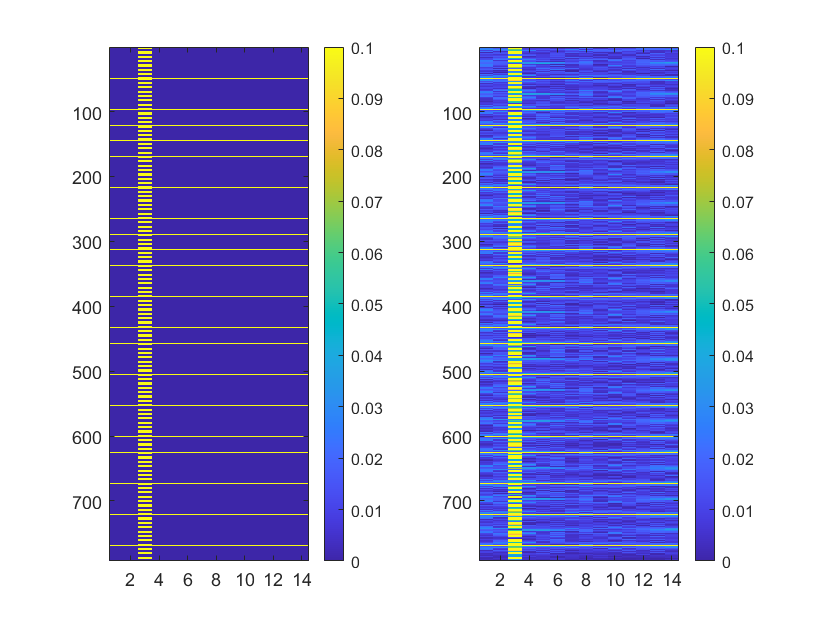


figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(:,end-14+1:end)), CRANGE); colorbar();
subplot(1,2,2); imagesc(abs(rxGrid_nodata  (:,end-14+1:end)), CRANGE); colorbar();

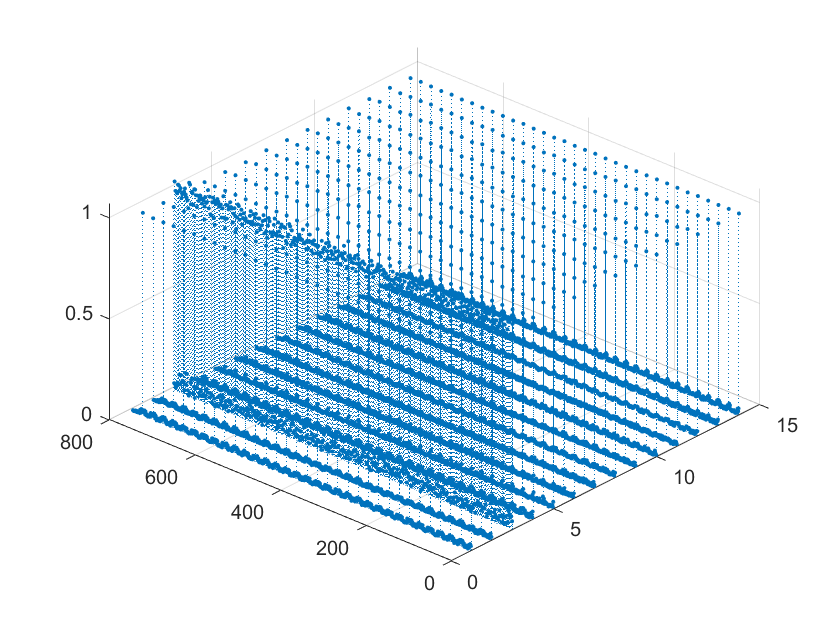


txx = txGrid_nodata(:,end-14+1:end);
rxx = rxGrid_nodata(:,end-14+1:end);
% rxx_a = abs(rxx);
% rxx_a (rxx_a>0.5) = rxx_a(rxx_a>0.5) - 0.80;
figure(); clf; stem3 (abs(rxx), '.:')

view([-47.929 44.176])

% view([-57.823 53.351])
leak = abs(abs(rxx) - abs(txx));
sum(rms(txx,1))

ans = 3.3607

sum(rms(rxx,1))

ans = 3.3606

sum(rms(rxx - txx, 1))

ans = 0.2461

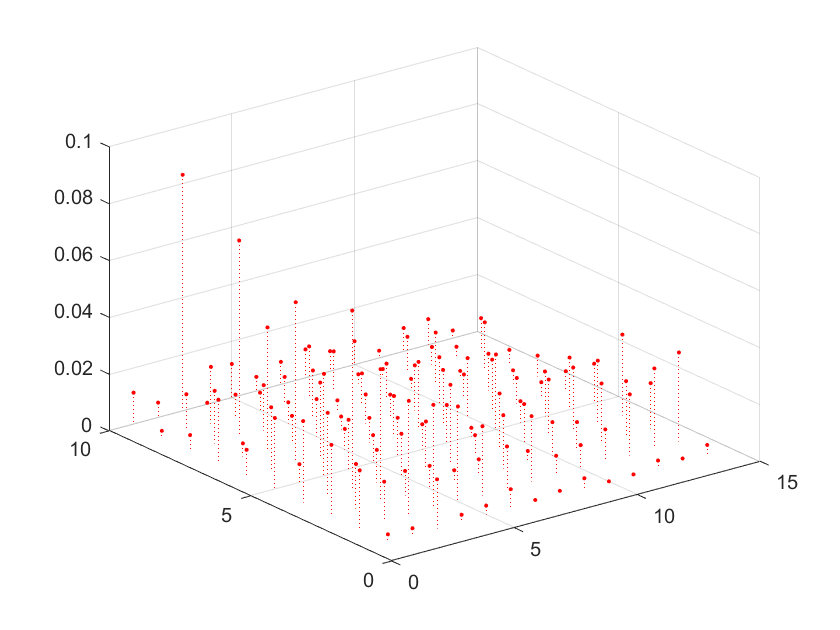

figure(); clf; stem3 (leak(1:10,:), 'r.:')

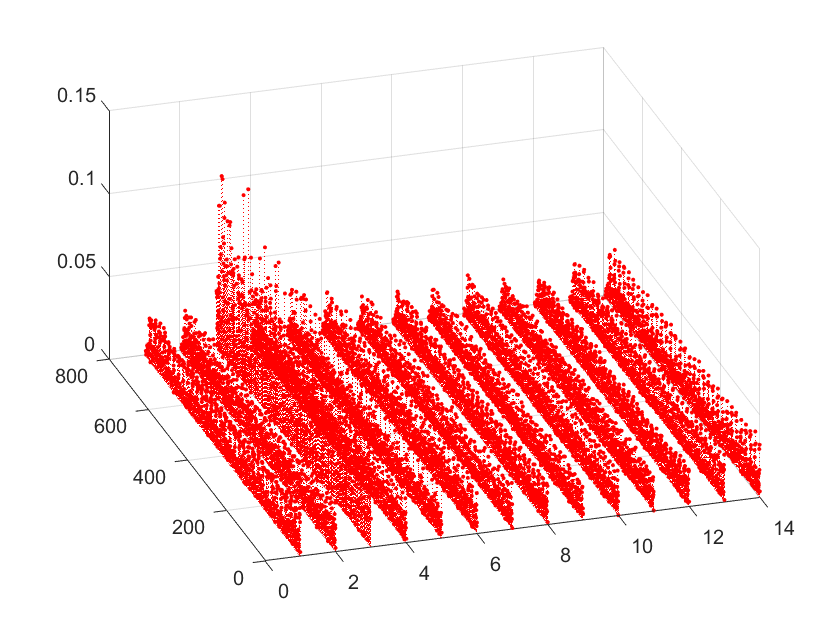

figure(); clf; stem3 (leak(:,:), 'r.:')
view([-17.5000 40.4101])

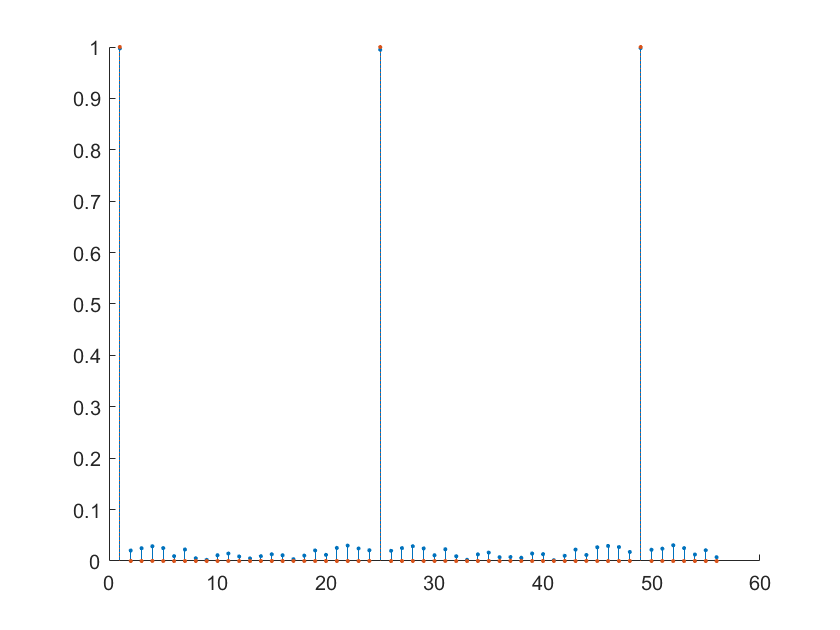


figure(); clf; hold on
stem (abs(rxx(1:14*4,1)), '.' ); 
stem (abs(txx(1:14*4,1)), '.:'); 
% ylim([0,1]/10)
hold off

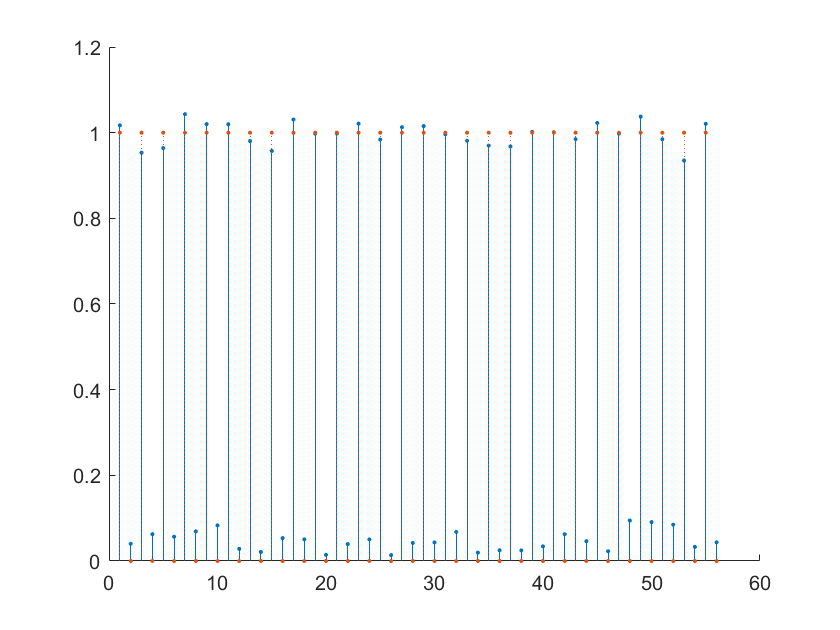

figure(); clf; hold on
stem (abs(rxx(1:14*4,3)), '.' ); 
stem (abs(txx(1:14*4,3)), '.:'); 
% ylim([0,1]/10))
hold off

## **Receiver 2 - Full Receiver with Proper Equalization and Commom Phase Errror (CPE) Compensation**

Before returning the equalized PDSCH symbols and decoded bits, the receiver performs these steps:

- Timing synchronization

- OFDM demodulation

- Channel estimation

- Equalization

- CPE estimation and correction

- PDSCH decoding

For the CPE estimation and correction step, the receiver uses the logical field `CompensateCPE` of the `simParameters` structure. Because the example does not use a propagation channel, the steps of timing synchronization, channel estimation, and equalization are not strictly necessary. **However, these steps help investigate the phase noise effects if you introduce a channel.**

The example shows the equalized constellation symbols, EVM, and bit error rate, with and without CPE compensation.

### **Case 1: Without CPE Compensation**

To disable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0.

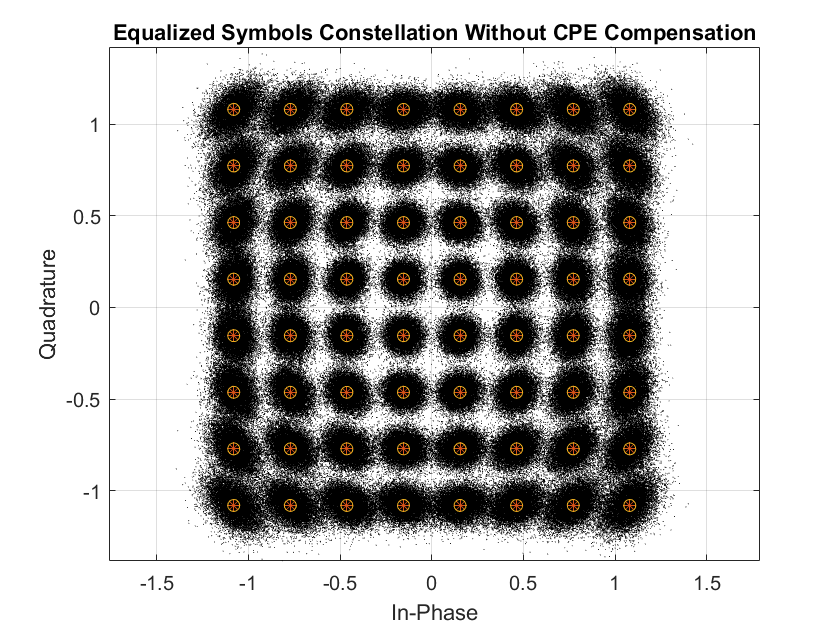

simParameters.CompensateCPE = 0;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
refSymbols         = getConstellationPoints(pdsch);
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Symbols Constellation Without CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
axis equal


% Display RMS EVM (Error Vector Magnitude)
evm = comm.EVM('ReferenceSignalSource', ...
               'Estimated from reference constellation', ...
               'ReferenceConstellation', refSymbols);

fprintf('RMS EVM (in percent) eq symbols w/o CPE compensation: %f%% \n', ...
         evm(eqSymbols))

RMS EVM (in percent) eq symbols w/o CPE compensation: 8.408854% 


% Display bit error rate
errorRate = nnz(rxbits-txbits)/numel(txbits);
fprintf('Bit error rate without CPE compensation: %f \n',errorRate)

Bit error rate without CPE compensation: 0.005004 


### **Case 2: With CPE Compensation**

To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

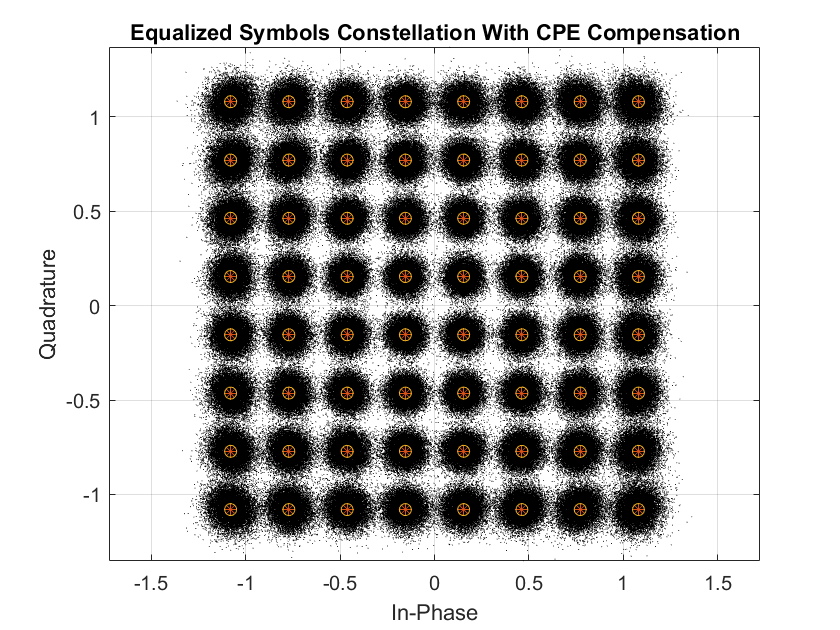

simParameters.CompensateCPE = 1;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Symbols Constellation With CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
axis equal


% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols with CPE compensation: %f%% \n',evm(eqSymbolsCPE))

RMS EVM (in percent) for equalized symbols with CPE compensation: 7.440295% 


% Display bit error rate
errorRateCPE = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate with CPE compensation: %f \n',errorRateCPE)

Bit error rate with CPE compensation: 0.001621 


### **Case 3 : CPE Compensation on a AGWN Fading Channel**

To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

#### Case 3.1 - First let see how the Channel is Changing due to Fading and How the Engergy in the Control DM-RS and PT-RS Control Symbols will be Dispersed by the Channel Effects (No Simullated Phase Noise Introduced Yet)            

% Parmaeters for each path
gain  = [0,     -3,     -3,     -3]';  % path gain in dB
dly   = [0, 200e-9, 300e-9, 100e-9]';  % path delays in seconds
aoaAz = [0,    180,   22.5,     45]';  % angles of arrival - Azim
aoaEl = [0,     20,     30,     40]';  % angles of arrival - Elev
% Mobile velocity vector in m/s
rxVel = [10,0,0]'; % (vx,vy,vz)

gain  = [0,     0,     0,     0]';  % path gain in dB
dly   = [0, 0, 0, 0]';  % path delays in seconds
aoaAz = [0,    0,   0,   0]';  % angles of arrival - Azim
aoaEl = [0,     0,     0,     0]';  % angles of arrival - Elev
% Mobile velocity vector in m/s
rxVel = [0,0,0]'; % (vx,vy,vz)

gain = mag2db(db2mag(gain)./ sum(db2mag(gain)))

gain =   -12.0412
  -12.0412
  -12.0412
  -12.0412





% Parameters for computing the SNR
Etx = 1;        % Average transmitted symbol energy
EsN0Avg = 20;   % Average SNR

% fdchan = FDChan(carrier, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
%     'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', EsN0Avg, 'fc', simParameters.Fc);

fdchan = FDChan(carrier, 'waveformConfig', waveformConfig, ...
                'gain', gain, 'dly', dly, ...
                'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                'rxVel', rxVel, 'Etx', Etx, ...
                'EsN0Avg', EsN0Avg, 'fc', simParameters.Fc)

FDChan->FDChan() Called

fdchan =   FDChan with properties:

     carrierConfig: [1×1 nrCarrierConfig]
    waveformConfig: [1×1 struct]
              gain: [4×1 double]
               dly: [4×1 double]
             aoaAz: [4×1 double]
             aoaEl: [4×1 double]
                fd: [4×1 double]
             rxVel: [3×1 double]
                fc: 6.0000e+10
       gainComplex: [4×1 double]
               Etx: 1
           EsN0Avg: 20
          symStart: [1×56 double]
              Verb: 1


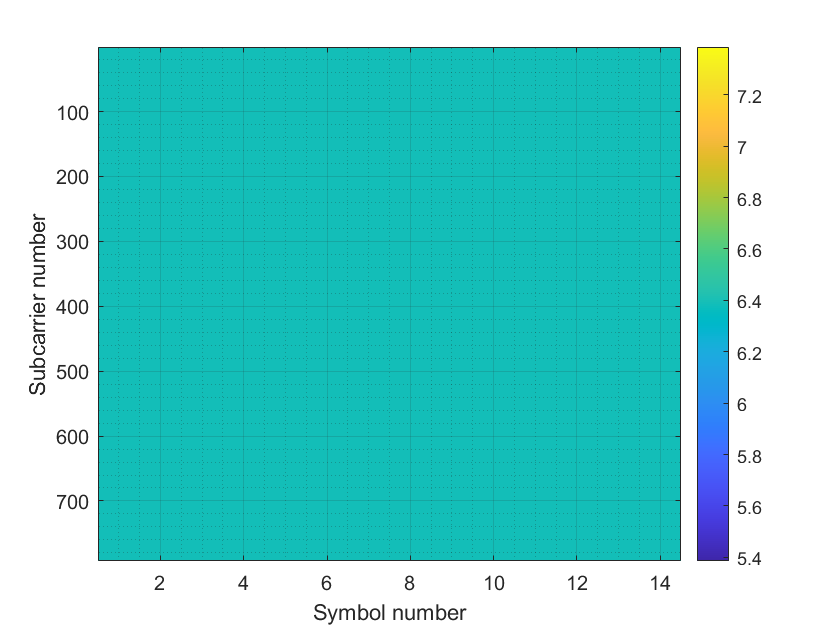


frNum = 0; sfNum = 0; slotNum = 0;
len = waveformConfig.SymbolsPerSlot;
idx = frNum * waveformConfig.SlotsPerSubframe*len + ...
      sfNum * len + 1;
slotGrid = txGrid(:, idx:idx+len-1);
[rxg_fd,chan,noiseVar] = fdchan.step(slotGrid, sfNum, slotNum); % Does one 792x14 at a time

%
chanSnr = 10*log10(abs(chan).^2/noiseVar);
figure(); clf; imagesc(chanSnr);
grid(gca,'minor'); grid on
colorbar();
xlabel('Symbol number');
ylabel('Subcarrier number');


frNum = 0; sfNum = 0; slotNum = 0;
len = waveformConfig.SymbolsPerSlot;
idx = frNum * 10  * waveformConfig.SlotsPerSubframe*len + ...
      sfNum * len + 1;
slotGrid = txGrid_nodata(:, idx:idx+len-1);
[rxg_fd,chan,noiseVar] = fdchan.step(slotGrid, sfNum, slotNum); % Does one 792x14 at a time

CRANGE=[0,.5]

CRANGE =          0    0.5000


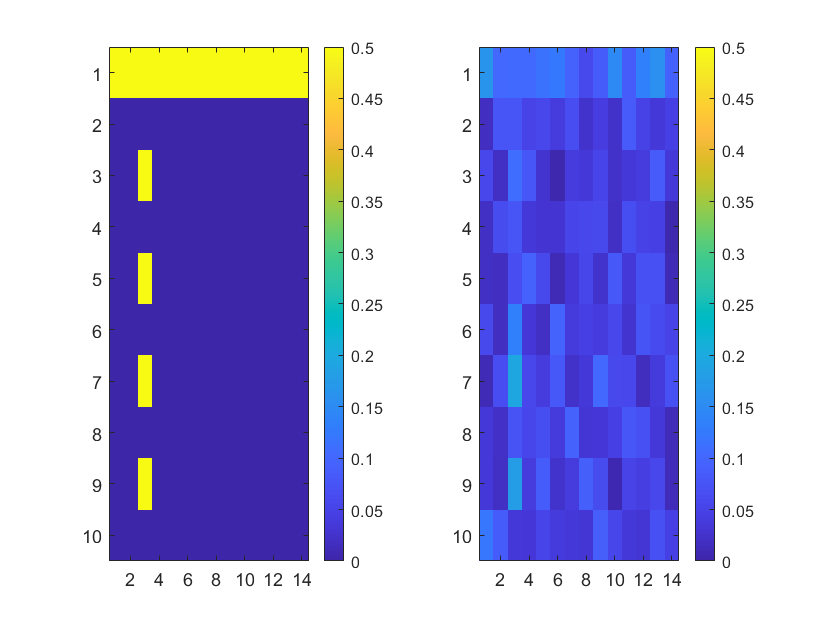

figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(1:10,end-14+1:end)),CRANGE); colorbar();
subplot(1,2,2); imagesc(abs(rxg_fd         (1:10,end-14+1:end)),CRANGE); colorbar();

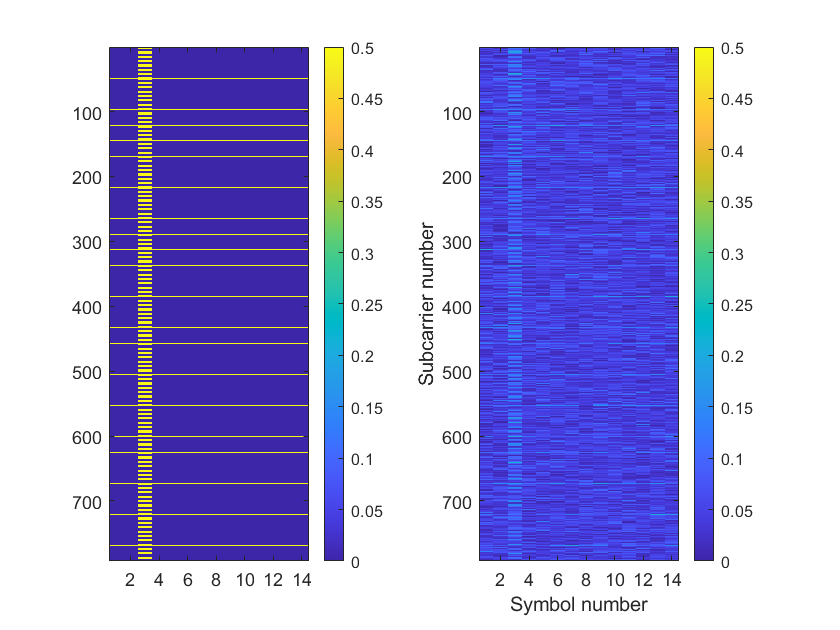


figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_nodata(:   ,end-14+1:end)),CRANGE); colorbar();
subplot(1,2,2); imagesc(abs(rxg_fd         (:   ,end-14+1:end)),CRANGE); colorbar();

colorbar();
xlabel('Symbol number');
ylabel('Subcarrier number');

#### Case 3.2 - Now we will introduce the Phase Noise Perturbations and observe the how the CPE compensation is able to mitigate the Phase Noise in present of Fading and Addititve Gaussian Noise.

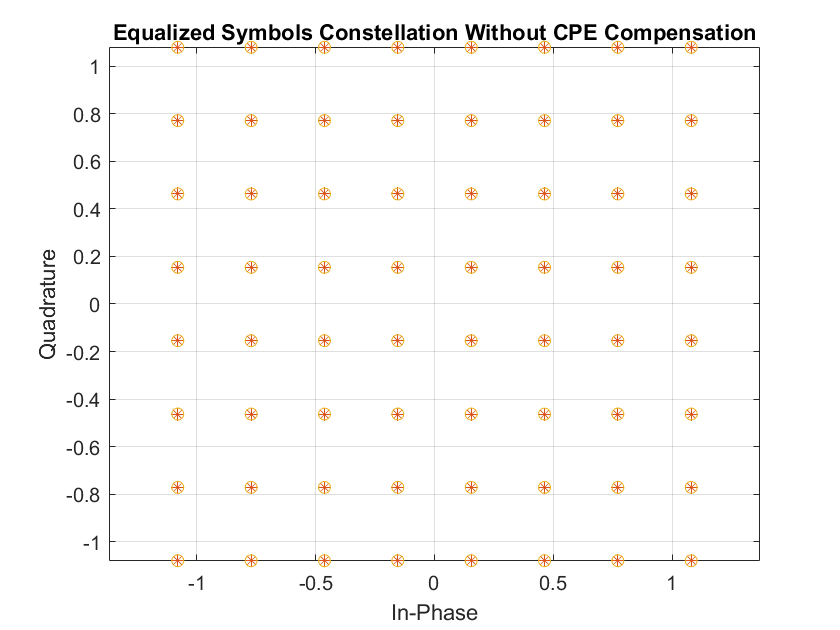

%% Get the number of slots in the waveform and number of symbols in a slot
% numSlots  = carrier.SlotsPerFrame*simParameters.NumFrames;
% nSlotSymb = carrier.SymbolsPerSlot;
% txGrid    = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);

rxFdGrid = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);
nsym=1;
for fr = 1:simParameters.NumFrames
   for sub_fr = 1:10 
       for slot = 1:waveformConfig.SlotsPerSubframe
           len = waveformConfig.SymbolsPerSlot;
           %fprintf("fr=%d sub_fr=%2d slot=%d nsym=[%4d,%4d]\n",fr,sub_fr,slot,nsym,nsym+len-1)           
           slotGrid = txGrid(:, nsym:nsym+len-1);
           [rxSlot,chan,noiseVar] = fdchan.step(slotGrid, sfNum, slotNum); % 792x14 at a time
           rxFdGrid(:, nsym:nsym+len-1) = rxSlot;
           nsym=nsym+waveformConfig.SymbolsPerSlot;
       end
   end
end


rxWaveform        = nrOFDMModulate(carrier,txGrid);

simParameters.CompensateCPE = 0;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
refSymbols         = getConstellationPoints(pdsch);
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Symbols Constellation Without CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
axis equal


% Display RMS EVM (Error Vector Magnitude)
evm = comm.EVM('ReferenceSignalSource', ...
               'Estimated from reference constellation', ...
               'ReferenceConstellation', refSymbols);

fprintf('RMS EVM (in percent) eq symbols w/o CPE compensation: %f%% \n', ...
         evm(eqSymbols))

RMS EVM (in percent) eq symbols w/o CPE compensation: 0.000000% 


% Display bit error rate
errorRate = nnz(rxbits-txbits)/numel(txbits);
fprintf('Bit error rate without CPE compensation: %f \n',errorRate)

Bit error rate without CPE compensation: 0.000000 


### **TBD Case 2: With CPE Compensation**

To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

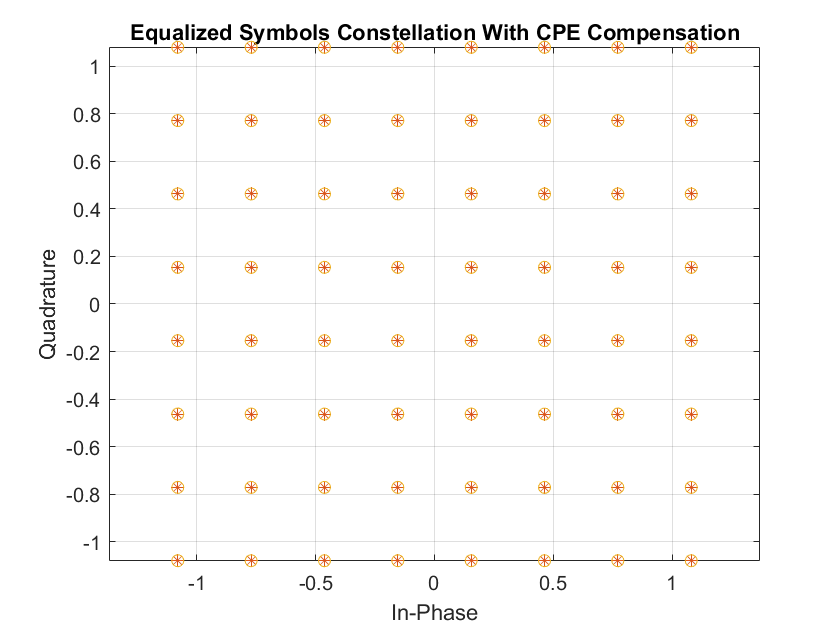

simParameters.CompensateCPE = 1;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Symbols Constellation With CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
axis equal


% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols with CPE compensation: %f%% \n',evm(eqSymbolsCPE))

RMS EVM (in percent) for equalized symbols with CPE compensation: 0.000000% 


% Display bit error rate
errorRateCPE = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate with CPE compensation: %f \n',errorRateCPE)

Bit error rate with CPE compensation: 0.000000 


## **Further Exploration TBD**

- To visualize the impact of phase noise, change the carrier frequency, subcarrier spacing, number of resource blocks, modulation scheme, and the number of frames.

- To see the effects of phase noise on the constellation, change the phase noise model.

- To analyze the effect of CPE compensation with different configurations, change the time and frequency density of PT-RS.

- Visualize the impacts of phase noise by including thermal noise and channel models.

## **Summary TBD**

This example demonstrates the impact of phase noise and shows how to estimate and correct CPE with PT-RS. The example also shows that CPE compensation reduces the EVM and improves bit error rate. The displayed constellation plot shows huge ICI in mmWave frequencies, **indicating that ICI compensation needs to be performed in addition to CPE compensation.**

## References*:*

(1) Wu, Songping, "Phase noise effects on OFDM : analysis and mitigation" (2004). Dissertations. 645. 

[https://digitalcommons.njit.edu/dissertations/645](https://digitalcommons.njit.edu/dissertations/645)

(2) Mathworks, "NR Phase Noise Modeling and Compensation" 

[https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html](https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html)

(3) [*An Overview of Phase Noise and Jitter*](http://literature.cdn.keysight.com/litweb/pdf/5990-3108EN.pdf) (PDF), Keysight Technologies, May 17, 2001

(4) Erdogan, Ahmet Yasin, "Analysis of the effects of phase noise and frequency offset in orthogonal frequency division multiplexing (OFDM) systems" (2004).

[https://core.ac.uk/download/pdf/36695447.pdf](https://core.ac.uk/download/pdf/36695447.pdf)

(5) Wikipedia [https://en.wikipedia.org/w/index.php?title=Phase_noise](https://en.wikipedia.org/w/index.php?title=Phase_noise)

## **---------------------------------------------------------------------------------------------**

## **Local Functions**

function [eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,params,rxWaveform)
% Returns equalized modulated symbols after performing the timing
% estimation, OFDM demodulation, channel estimation, MMSE equalization,
% CPE estimation and correction, and PDSCH decoding.

    % Get the current slot number, number of slots, number of symbols
    % per slot, and total number of symbols
    nSlot = carrier.NSlot;
    numSlots = carrier.SlotsPerFrame*params.NumFrames;
    nSlotSymb = carrier.SymbolsPerSlot;
    numTotalSymbols = numSlots*nSlotSymb;

    % Get reference grid with DM-RS symbols
    dmrsSymCell = cell(1,numSlots);
    dmrsIndCell = cell(1,numSlots);
    refGrid = zeros(carrier.NSizeGrid*12,numTotalSymbols,pdsch.NumLayers);
    for NSlot = 0:numSlots-1
        carrier.NSlot = NSlot;
        slotGrid = nrResourceGrid(carrier,pdsch.NumLayers);
        dmrsSymCell{NSlot+1} = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndCell{NSlot+1} = nrPDSCHDMRSIndices(carrier,pdsch);
        slotGrid(dmrsIndCell{NSlot+1}) = dmrsSymCell{NSlot+1};
        refGrid(:,NSlot*nSlotSymb+1:(NSlot+1)*(nSlotSymb),:) = slotGrid;
    end

    % Perform timing estimation and correction
    carrier.NSlot = nSlot;
    offset = nrTimingEstimate(carrier,rxWaveform,refGrid);
    waveformSync = rxWaveform(1+offset:end,:);

    % Perform OFDM demodulation on the received data to recreate the
    % resource grid, including padding in the event that practical
    % synchronization results in an incomplete slots being demodulated
    rxGrid = nrOFDMDemodulate(carrier,waveformSync);
    [K,L,R] = size(rxGrid);
    if (L < numTotalSymbols)
        rxGrid = cat(2,rxGrid,zeros(K,numTotalSymbols-L,R));
    end

    % Declare storage variables
    eqSymbols = [];  % equalized symbols for constellation plot
    rxbits = [];

    for NSlot = 0:numSlots-1
        % Extract grid for current slot
        currentGrid = rxGrid(:,NSlot*nSlotSymb+(1:nSlotSymb),:);

        % Get the PDSCH resources
        carrier.NSlot = NSlot;
        dmrsSymbols = dmrsSymCell{NSlot+1};
        dmrsIndices = dmrsIndCell{NSlot+1};
        ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
        ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);

        % Channel estimation
        [estChannelGrid,noiseEst] =  ...
           nrChannelEstimate(currentGrid,dmrsIndices,dmrsSymbols,...
           "CDMLengths",pdsch.DMRS.CDMLengths);

        % Get PDSCH resource elements from the received grid
        [pdschRx,pdschHest] = ...
           nrExtractResources(pdschIndices,currentGrid,estChannelGrid);

        % Equalization
        pdschEq = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Common phase error (CPE) estimation and correction
        if params.CompensateCPE
            % Initialize temporary grid to store equalized symbols
            tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);

            % Extract PT-RS symbols from received grid and estimated
            % channel grid
            [ptrsRx,ptrsHest,~,~,~,ptrsLayerIndices] = ...
                nrExtractResources(ptrsIndices,currentGrid,estChannelGrid,tempGrid);

            % Equalize PT-RS symbols and map them to tempGrid
            ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
            tempGrid(ptrsLayerIndices) = ptrsEq;

            % Estimate the residual channel at the PT-RS locations in
            % tempGrid
            cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);

            % Sum estimates across subcarriers, receive antennas, and
            % layers. Then, get the CPE by taking the angle of the
            % resultant sum
            cpe = angle(sum(cpe,[1 3 4]));

            % Map the equalized PDSCH symbols to tempGrid
            tempGrid(pdschIndices) = pdschEq;

            % Correct CPE in each OFDM symbol within the range of reference
            % PT-RS OFDM symbols
            if numel(pdschIndicesInfo.PTRSSymbolSet) > 0
                symLoc = pdschIndicesInfo.PTRSSymbolSet(1) ...
                        +1:pdschIndicesInfo.PTRSSymbolSet(end) +1;
                tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
            end

            % Extract PDSCH symbols
            pdschEq = tempGrid(pdschIndices);
        end

        % Store the equalized symbols and output them for all the slots
        eqSymbols = [eqSymbols; pdschEq]; %#ok<AGROW>

        % Decode the PDSCH symbols and get the hard bits
        eqbits = nrPDSCHDecode(carrier,pdsch,pdschEq);
        for i = 1:numel(eqbits)
            rxbits = [rxbits; double(eqbits{i}<0)]; %#ok<AGROW>
        end

    end

end

function sym = getConstellationPoints(pdsch)
%getConstellationPoints Constellation points
%   SYM = getConstellationPoints(PDSCH) returns the constellation points
%   SYM based on modulation schemes provided in PDSCH configuration object.
    sym = [];
    modulation = string(pdsch.Modulation);  % Convert modulation scheme to string type
    ncw = pdsch.NumCodewords;               % Number of codewords
    if ncw == 2 && (numel(modulation) == 1)
        modulation(end+1) = modulation(1);
    end
    % Get the constellation points
    for cwIndex = 1:ncw
     qm = strcmpi(modulation(cwIndex),{'QPSK','16QAM','64QAM','256QAM'})*[2 4 6 8]';
     sym = [sym; nrSymbolModulate(reshape(de2bi(0:2^qm-1,qm,'left-msb')',[],1), ...
            modulation(cwIndex))]; %#ok<AGROW>
    end

end

function phase_noise_psd = PN_Model2Use(f, fc, model)
%   Phase noise characteristic with pole-zero model
%   PSD = hPhaseNoisePoleZeroModel(F,Fc,model) generates the phase noise
%   characteristic PSD in dBc/Hz for the frequency offset values specified
%   by vector F for the carrier frequency Fc. 
%   
%   Models:  
%   
%   'A' :::  parameters used are obtained from the response of a practical oscillator 
%   operated at 30 GHz, as per 3Gpp model R1-163984. Similarly, when MODEL is set to 
% 
%   'B' :::  parameters used are obtained from the response of a practical
%   oscillator operated at 60 GHz, as also specified in 2Gpp doc R1-163984. 
%   
%   'C' ::: the parameters used are obtained from the response of a
%   practical oscillator operated at 29.55 GHz, as specified in TR 38.803.
%
%   More info on https://www.3gpp.org/ftp/tsg_ran/WG1_RL1/TSGR1_85/Docs/R1-163984.zip
%   https://portal.3gpp.org/desktopmodules/Specifications/SpecificationDetails.aspx?specificationId=3069
%   Based on 
%   https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html
%
    fcBase = 30e9;
    fz     = [1.8 2.2 40]*1e6;
    fp     = [0.1 0.2 8]*1e6;
    alphaz = [2 2 2];
    alphap = [2 2 2];
    psd0   = -79.4;  
    
    % Pole/zeros and psd0
    switch model
            case 'A'
                % Parameter set A (R1-163984)
                fcBase = 30e9;
                fz     = [1.8 2.2 40]*1e6;
                fp     = [0.1 0.2 8]*1e6;
                alphaz = [2 2 2];
                alphap = [2 2 2];
                psd0   = -79.4;
            case 'B'
                % Parameter set B (R1-163984)
                fcBase = 60e9;
                fz     = [0.02 6 10]*1e6;
                fp     = [0.005 0.4 0.6]*1e6;
                alphaz = [2 2 2];
                alphap = [2 2 2];
                psd0   = -70;
            case 'C'
                % Parameter set C (TR 38.803)
                fcBase = 29.55e9;
                fz     = [3e3 550e3 280e6];
                fp     = [1 1.6e6 30e6];
                alphaz = [2.37 2.7 2.53];
                alphap = [3.3 3.3 1];
                psd0   = 32;
    end

    % Compute numerator
    num = ones(size(f));
    for idx = 1:numel(fz)
        num = num.*(1 + (f./fz(idx)).^alphaz(idx));
    end

    % Compute denominator
    den = ones(size(f));
    for idx = 1:numel(fp)
        den = den.*(1 + (f./fp(idx)).^alphap(idx));
    end

    % Compute psd
    phase_noise_psd = 10*log10(num./den) + psd0 + 20*log10(fc/fcBase);

end
